% Importing Square and Rectangle
    SquareImg = imread('square.jpg');
    RectImg = imread('rectangle.jpg');

% 5.2.10

% Need to create an image of any size. Cannot use built in matlab function 
% Creating Function for DST S matrix
function S= DST(n)
    % Creating a vector of 0's to allocate space
    S = zeros(n);
    % Creating for loop to create S matrix. Each cell will be equal to 
        % s_{i,j} = sqrt(2/n) * sin(pi*(i-1/2)*(j-1/2)/n)
    % Outer loop, which is rows
        for i = 1:n % Makes rows n large
            % Inner Loop, which is columns
            for j = 1:n
                % Setting the value of each cell via the DST function 
                S(i,j) = sqrt(2/n) * sin(pi*(i-1/2)*(j-1/2)/n);   
            end
        end
end

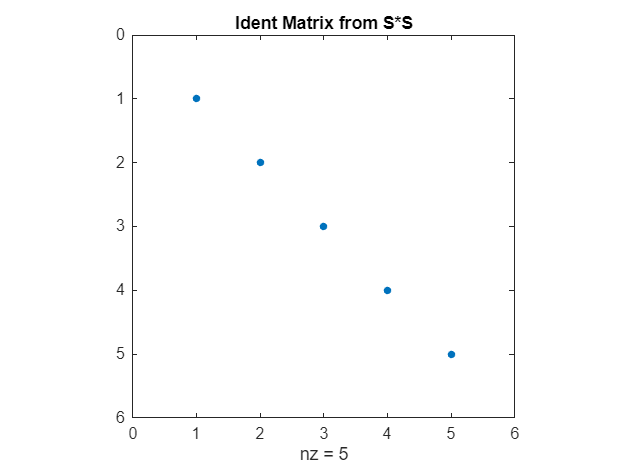

% 5.2.11

% Need to verify that a 5x5 S matrix S is equal to the inverse
% We can do this by showing that S * S = I

% Calling DST s matrix function with 5
    Matrix_Size = 5;
    S = DST(Matrix_Size);
% Will multiply S by S to ident matrix, then use spy to show the identity
% matrix
    S_ident = S * S;
% will round off S_ident so spy can show identity matrix
    f = figure(1);
    spy(round(S_ident,0))
    title('Ident Matrix from S*S')
% Export image as jpg
    exportgraphics(f, '5.2.11 Proof of S.jpg', 'Resolution', 300);     % high-DPI jpg    

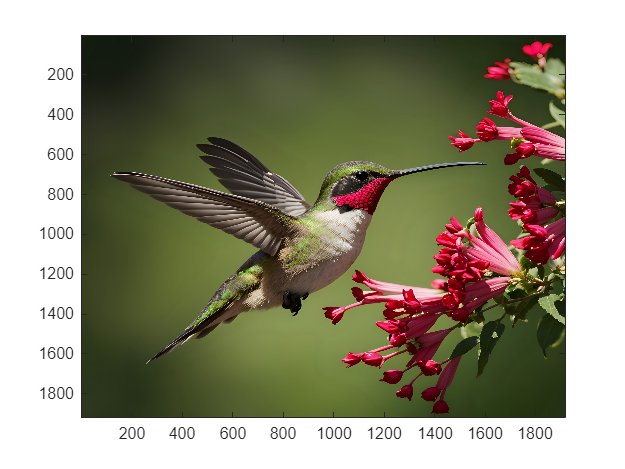

% 5.2.12
% Code form 5.1.1
% We need to determine what steps need to be taken to undo the 2
% Dimensional DST
   X = imread('square.jpg');
       imagesc(X)

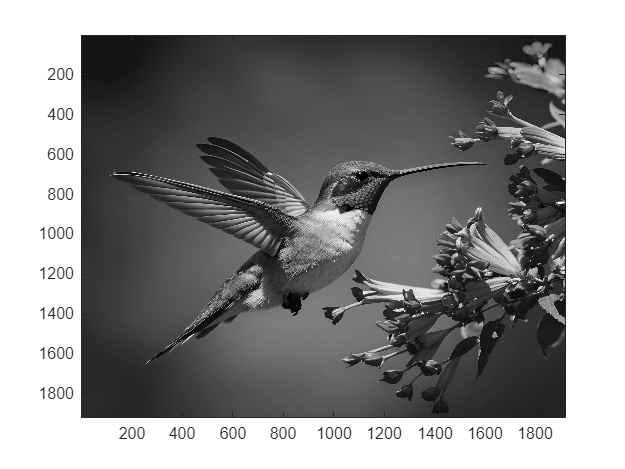

   % Convert X matrix to double datatype
       X_double = double(X);
       % Setting Variable that will be used in question below
           R = X_double(:,:,1);
           G = X_double(:,:,2);
           B = X_double(:,:,3);  
   % Convert to double (data type) greyscale image and read greyscale image 
       X_gray= X_double(:,:,1)/3.0 + X_double(:,:,2)/3.0 + X_double(:,:,3)/3.0;
           % Side note, this is taking the average of each intensity and
           % linearly combining it into 1 matrix
       %imagesc(uint8(X_gray))
       %colormap('gray') 
   % Set the size for our gray scale
           [m,n] = size(X_gray);
           S_m = DST(m);
           S_n = DST(n);
   % Create our original Function Y = S * X_g * S
       Y = S_m * X_gray * S_n;
   % Create our reconstructed Function
       X_gray_recon = S_m * Y * S_n;
   % Display both our Gray Scale and our Reconstructed Gray Scale
           figure(1);
           imagesc((X_gray))
           colormap('gray');

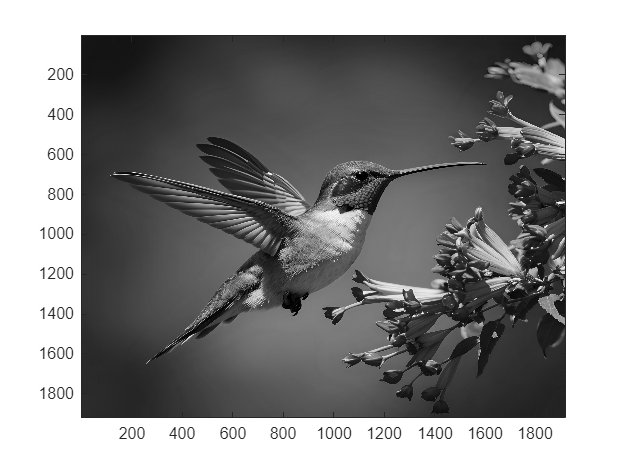



           figure(2);
           imagesc((X_gray_recon));
           colormap('gray'); 

   % Creating file images
        % Creating new Image
            imwrite(uint8(X_gray),'5.2.12_Original.jpg')
        % Creating new Image
            imwrite(uint8(X_gray_recon),'5.2.12_Reconstruction.jpg')

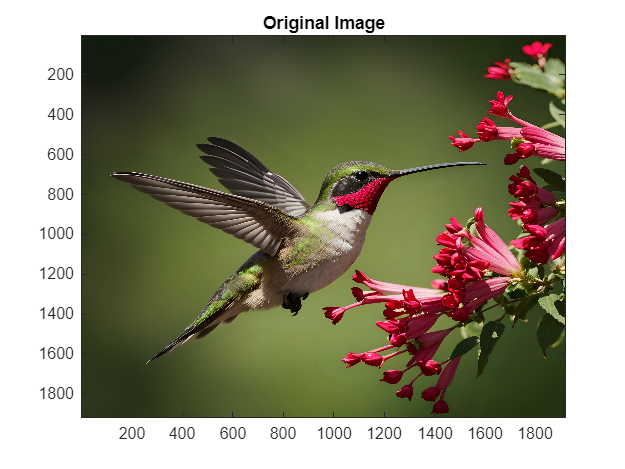

% 5.2.13

% In this section, we are compressing an image, each color channel

% Creating a function for the compression alogorithm for easy repeatability

function [Img_matrix] = Compression(Img, p) % Takes matrix and p size as inputs and outputs Img_matrix
    % Transform the image with DST
        [m,n,~] = size(Img);
            % creating DST ident matrixes 
        S_rows = DST(m);
        S_cols = DST(n);
            % Transforming image, each color matrix to DST
        Img_matrix = zeros(m,n,3); % allocates a zero matrix for speed
        for k = 1:3
            Img_matrix(:,:,k) = S_rows * Img(:,:,k) * S_cols;
        end 

    % Now we will apply our compression algorithm 
        
            % For loop for rows
            for i = 1:m
                % For loop for columns
                for j = 1:n
                    % if loop that discards higher "frequencys" of the DST,
                    % which is less noticible than lower frequencys 
                    if (i+j > p*2*n)                       
                            Img_matrix(i,j,1:3) = 0;     
                    end              
                end 
            end
    % Now compression is over, we need to undo our DST transformation
        
        for k = 1:3
            Img_matrix(:,:,k) = S_rows * Img_matrix(:,:,k) * S_cols;
        end 
end

% Now we will test With a value of 1 (no compression)

        % Create an image matrix to put into our function
     Img_comp_1 = double(SquareImg);
        % Put image through function
     p = 1; % Compression factor
     Img_comp_1 = Compression(Img_comp_1,p);
        % Output original and compressed
     
     imagesc(uint8(SquareImg))
     title('Original Image')

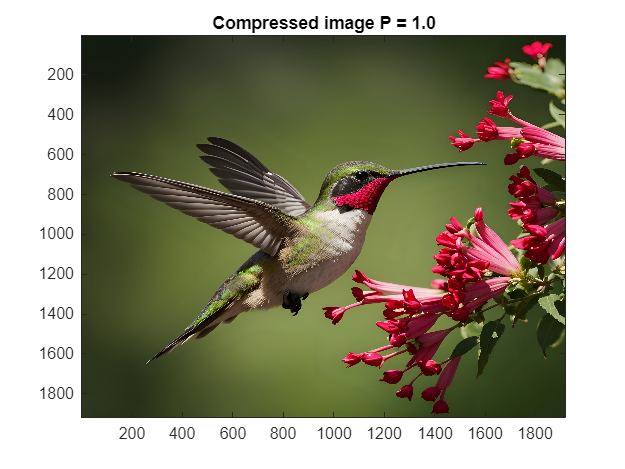

  
     
     imagesc(uint8(Img_comp_1));
     title('Compressed image P = 1.0')

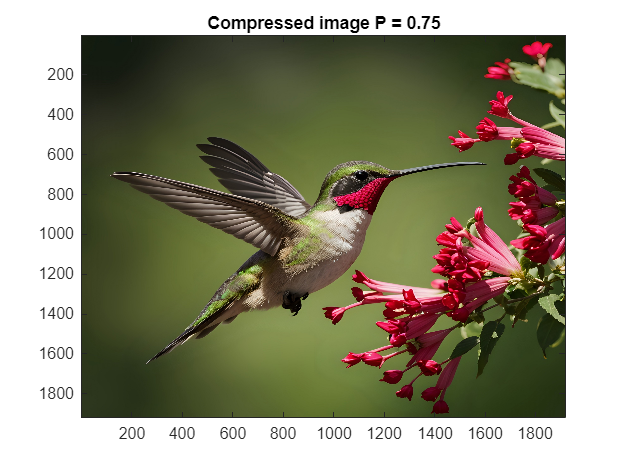

        
     % Creating file images
        % Creating new Image
            imwrite(uint8(SquareImg),'5.2.13_Original.jpg')
        % Creating new Image
            imwrite(uint8(Img_comp_1),'5.2.13_Compressed_P=1.jpg')
% Now we will test With a value of 0.75 

        % Create an image matrix to put into our function
     Img_comp_2 = double(SquareImg);
        % Put image through function
     p = 0.75; % Compression factor
     Img_comp_2 = Compression(Img_comp_2,p);
        % Output original and compressed

     imagesc(uint8(Img_comp_2));
     title('Compressed image P = 0.75')

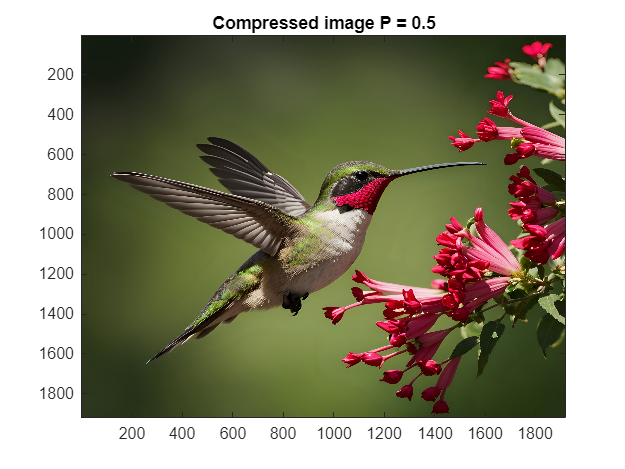

        
     % Creating file images
        % Creating new Image
            imwrite(uint8(Img_comp_1),'5.2.13_Compressed_P=0.75.jpg')
% Now we will test With a value of 0.5

        % Create an image matrix to put into our function
     Img_comp_3 = double(SquareImg);
        % Put image through function
     p = 0.50; % Compression factor
     Img_comp_3 = Compression(Img_comp_3,p);
        % Output original and compressed

     imagesc(uint8(Img_comp_3));
     title('Compressed image P = 0.5')

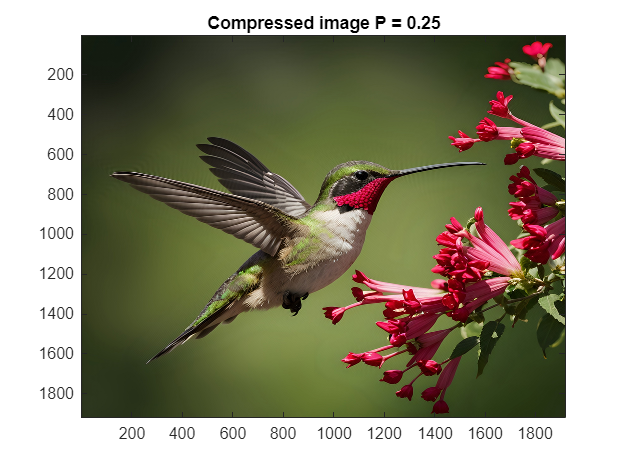

        
     % Creating file images
        % Creating new Image
            imwrite(uint8(Img_comp_3),'5.2.13_Compressed_P=0.5.jpg')
% Now we will test With a value of 0.25

        % Create an image matrix to put into our function
     Img_comp_4 = double(SquareImg);
        % Put image through function
     p = 0.25; % Compression factor
     Img_comp_4 = Compression(Img_comp_4,p);
        % Output original and compressed

     imagesc(uint8(Img_comp_4));
     title('Compressed image P = 0.25')

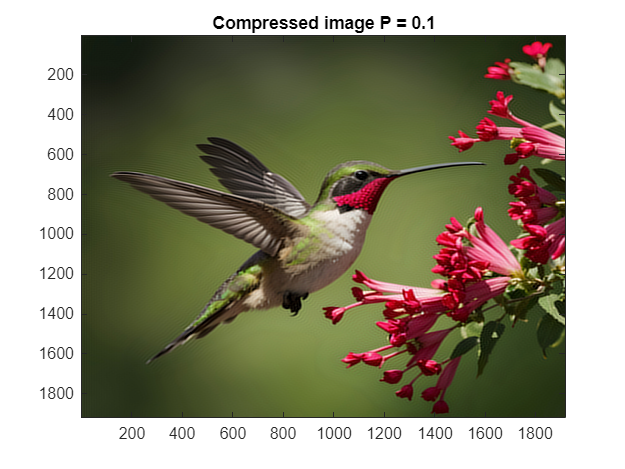

        
     % Creating file images
         % Creating new Image
            imwrite(uint8(Img_comp_4),'5.2.13_Compressed_P=0.25.jpg')
% Now we will test With a value of 0.1

        % Create an image matrix to put into our function
     Img_comp_5 = double(SquareImg);
        % Put image through function
     p = 0.1; % Compression factor
     Img_comp_5 = Compression(Img_comp_5,p);
        % Output original and compressed

     imagesc(uint8(Img_comp_5));
     title('Compressed image P = 0.1')

        
     % Creating file images
         % Creating new Image
            imwrite(uint8(Img_comp_5),'5.2.13_Compressed_P=0.1.jpg')



     
